# fit the model

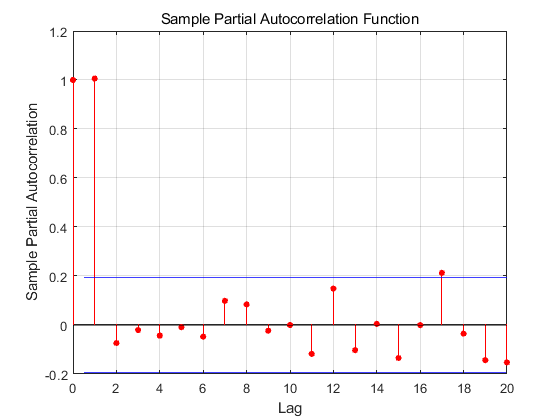

parcorr(exp7.price)

Mdl = arima(2,1,2);
model=estimate(Mdl,exp7.price(1:90))

 
    ARIMA(2,1,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.13072      0.053775         2.4309         0.015061
    AR{1}       0.024358      0.036958        0.65907          0.50985
    AR{2}        0.90993      0.036224         25.119      3.0595e-139
    MA{1}              0      0.088577              0                1
    MA{2}             -1      0.075863        -13.182       1.1185e-39
    Variance      16.845        2.3818         7.0722       1.5254e-12



model =   arima - 属性:

     Description: "ARIMA(2,1,2) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 3
               D: 1
               Q: 2
        Constant: 0.130723
              AR: {0.0243578 0.909931} at lags [1 2]
             SAR: {}
              MA: {-1} at lag [2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 16.8448

## forcast


[pred,ymse]=forecast(model,15,exp7.price(1:90))

pred =   277.7530
  278.6506
  281.4903
  282.5069
  285.2463
  286.3688
  289.0195
  290.2362
  292.8085
  294.1089


ymse =    16.8448
   34.5202
   49.2426
   64.6011
   77.4666
   90.8138
  102.0549
  113.6557
  123.4761
  133.5602



h1 = plot(exp7.price,'Color',[.7,.7,.7])

h1 =   Line - 属性:

              Color: [0.7000 0.7000 0.7000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×105 double]
              YData: [1×105 double]
              ZData: [1×0 double]

  显示 所有属性


hold on
h2 = plot(91:105,pred,'b','LineWidth',2)

h2 =   Line - 属性:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [91 92 93 94 95 96 97 98 99 100 101 102 103 104 105]
              YData: [277.7530 278.6506 281.4903 282.5069 285.2463 286.3688 289.0195 290.2362 292.8085 294.1089 296.6120 297.9870 300.4288 301.8702 304.2579]
              ZData: [1×0 double]

  显示 所有属性


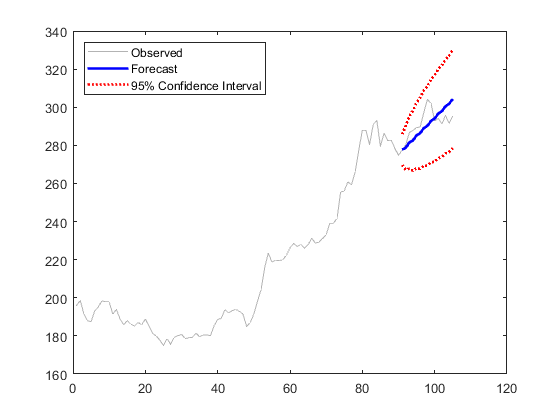

h3= plot(91:105,pred + 1.96*sqrt(ymse),'r:',...
		'LineWidth',2);
plot(91:105,pred - 1.96*sqrt(ymse),'r:',...
		'LineWidth',2);

legend([h1 h2 h3],'Observed','Forecast',...
		'95% Confidence Interval','Location','NorthWest');
hold off